% Header

# User data input

**Disclaimer: **Many components of the syntax and descriptions are paraphrased from MATLAB's help files. The below content is not meant to be comprehensive but rather a useful starting point. 

# input -- Request User Input via Command Window

Request user input

## Syntax

- `x = input(prompt) `          `<-` Numerical input

- `chr = input(prompt,'s')``     <-` Character array input

## Description

`x = input(prompt)` displays the text in `prompt` and waits for the user to input a value and press the **Return **key. The user can enter expressions, like `pi/4` or `rand(3)`, and can use variables in the workspace.

- If the user presses the **Return** key without entering anything, then `input` returns an empty matrix.

- If the user enters an invalid expression at the prompt, then MATLAB® displays the relevant error message, and then redisplays the prompt.

`chr = input(prompt,'s')` returns the entered **text**, without evaluating the input as an expression.

For this demo, run the commands and make notes about their behavior.  

### Example - input for numbers

time = input('Enter the length of wait to receive service [minutes]: ')

**Student Notes:**  ####=assigns number to time

format:

variable name=always have variable on left hand side

variable=input('prompt')

stored as a numeric

Test cases

- enter scalar

- matrix-puts in matrix if do [], if not repeats

- nothing -skips, [ ]

- text-goes again, if do " " or ' 'puts into value

### Example - input for text

name = input('Enter the technician''s name that assisted you today: ','s') % implies its a string

**Student Notes:**  ####

variable=input('prompt')

- number-number as a character array

- text-text as a character arra

- nothing-", empty character array

# questdlg -- Question Dialog Box -- Request User Input -- Pick a Button

## Syntax

- `answer = questdlg(quest)``                  <-` Question | no title | Yes/No/Cancel

- `answer = questdlg(quest,dlgtitle)  ``       <-` Question | w/ title | Yes/No/Cancel

- `answer = questdlg(quest,dlgtitle,defbtn)``  <-` Question | w/ title | Yes/No/Cancel + def button

- `answer = questdlg(quest,dlgtitle,btn1,btn2,defbtn)` `<- `Question | w/ title | 2 cust buttons + def button

- `answer = questdlg(quest,dlgtitle,btn1,btn2,btn3,defbtn)` `<- `Question | w/ title | 3 cust buttons + def button

## Description

`answer` `=` `questdlg(quest) `creates a modal dialog box that presents a question and returns the user's response -- `'Yes'`, `'No'`, `'Cancel'`, or `''`.

By default, the dialog box has three standard buttons, labeled **Yes**, **No**, and **Cancel**.

- If the user clicks one of these buttons, then the `answer` value is the same as the label of the pressed button.

- If the user clicks the close button (X) on the dialog box title bar or presses the **Esc** key, then the `answer` value is an empty character vector (' ').

- If the user presses the **Return** key, then the `answer` value is the same as the label of the default button selection. In this case, `'Yes'`.

### **Example - questdlg w/ default buttons**

Survey = questdlg('Would you be willing to take a follow up survey about your visit?')

**Student Notes:**  ####-didn't specify survey so default

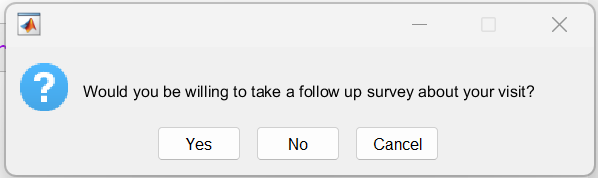

- yes-character array of input

- no-character array of input

- cancel-character array of input

- x-empty character

variable=questdlg('Prompt')

### **Example - questdlg w/ customized buttons & default option picked**

Satisfaction = questdlg('How satisfied were you?','Satisfaction Survey', ...
    'Very Satisfied','Meh','Not at all Satisfied','Meh') % meh is the default that is highlighted , need the highlighted one because it requires a default 

**Student Notes:**  ####

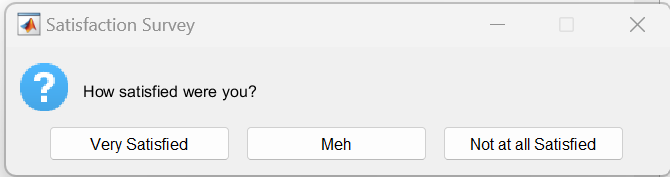

format: 

variable=questdlg('Prompt','dlgtitle', 'option 1', 'option 2' ,'defoption')

# listdlg -- List Dialog Box -- Request User Input -- Pick from a List

Create list selection dialog box

## Syntax

- `[indx,tf] = listdlg('ListString',list) `             `<- `Multi-pick list | no prompt | no title 

- `[indx,tf] = listdlg('ListString',list,Name,Value)`   `<- `Pick list | general application

`         ... most common application in ENGR 1410 (<- Single-pick list | has prompt | no title`

- `[indx,tf] = listdlg('ListString',list,'PromptString',prompt, 'SelectionMode','single')`

## Description

`[indx, tf`[](https://localhost:31515/static/help/matlab/ref/listdlg.html?searchHighlight=listdlg&searchResultIndex=1#d122e748745)`] =` `listdlg``('ListString',list)` creates a modal dialog box that allows the user to select one or more items from the specified list.

The `list` value is the list of items to present in the dialog box.

The function returns two output arguments, `indx` and `tf` containing information about which items the user selected.

The dialog box includes **Select all**, **Cancel**, and **OK** buttons. You can limit selection to a single item by using the name-value pair, `'SelectionMode','single'`.  If you do not include the `'SelectionMode','single' `name-value pair, then you will have the option to select multiple entries, or alternatively specify `'SelectionMode','multiple' `to explicitly allow the user to select multiple items.

### **Example - listdlg w/ single selection**

Departments = {'Shipping', 'Receiving', 'Computing', 'Billing', 'Service'} % must be a cell array

Departments = 1×5 cell array
    {'Shipping'}    {'Receiving'}    {'Computing'}    {'Billing'}    {'Service'}


[Dept,tf] = listdlg('PromptString','Select the department of service', ...
    'ListString',Departments,'SelectionMode','single') % dept is variable so no quotes, selection mode, 'single'=select 1, 'multiple'=select many with shift or ctrl

Dept = 1

tf = 1

MyDept=Departments{Dept} %indexes into the cell 

MyDept = 'Shipping'

**Student Notes:**  property names and variables 

'PromptString','Select the department of service', ... need to put propt string first

[Dept,tf]== Dept gives location of selection, logical gives result (0 or 1)

Formatt:[location, logical]=listdlg('Property name', 'property value'), no order for this, just must be a pair

logical value=0 if cancel or x

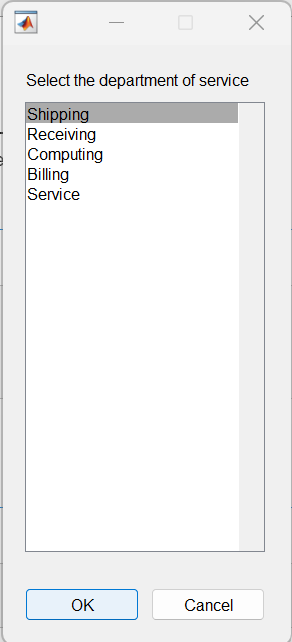

### **Example - listdlg w/ multiple selection**

[Dept,tf] = listdlg('PromptString','Select the department of service', ...
    'ListString',Departments,'SelectionMode','multiple') 

**Student Notes:**  ####

# inputdlg -- Input Dialogue Box -- Request User Input via dialogue box

Create dialog box to gather user input

## Syntax

- `answer = inputdlg(prompt)`

- `answer = inputdlg(prompt,dlgtitle) `

## Description

`answer = inputdlg(prompt) `creates a modal dialog box containing one or more text edit fields and returns the values entered by the user. The return values are elements of a cell array of character vectors. The first element of the cell array corresponds to the response in the edit field at the top of the dialog box. The second element corresponds to the next edit field response, and so on.

Check out the help file for information on changing the size of the box, setting default values and other options.

### **Example - inputdlg with 1 question**

company = inputdlg('Enter your help ticket reference code: ') % CELL ARRAY

**Student Notes:**  ####

### **Example - inputdlg with multiple questions and title**

myQuestions = {'Your Name: ', 'Age: '}

myQuestions = 1×2 cell array
    {'Your Name: '}    {'Age: '}


company = inputdlg(myQuestions,'Questions about you') %{2x1}, questions about you is name of dialog box

company = 2×1 cell array
    {0×0 char}
    {0×0 char}


**Student Notes:**  ####

FavMovieA=inputdlg('what is ur fav movie?','s')

FavMovieB=input('fav movie time')

Flavors={'coco','vanilla','strawberry'}
bro=listdlg('PromptString','flavor?','ListString',Flavors)
Selected_Flavor=Flavors{bro}


class=inputdlg( 'My Favorite Class is...', 's')
Number=inputdlg( 'We have ___ assignments a week,')
Teacher=inputdlg( 'and the teacher is really...', 's')
Exam=inputdlg( 'I really love the ___ exams', 's')

Questions={'My Favorite Class is...','We have ___ assignments a week,','and the teacher is really...','I really love the ___ exams',}
Bro=inputdlg(Questions,'answer plz')

Questions={'My Favorite Class is...','We have ___ assignments a week,','and the teacher is really...','I really love the ___ exams',}

Questions = 1×4 cell array
    {'My Favorite Class is...'}    {'We have ___ assignments a week,'}    {'and the teacher is really...'}    {'I really love the ___ exams'}


Bro=inputdlg(Questions,'answer plz')

Bro = 4×1 cell array
    {'2'}
    {'2'}
    {'2'}
    {'2'}


while isempty(Bro)
    Questions={'My Favorite Class is...','We have ___ assignments a week,','and the teacher is really...','I really love the ___ exams',}
    Bro=inputdlg(Questions,'answer plz')
    if ~isempty(Bro)
        fprintf('My Favorite Class is %s . We have %s assignments a week, and the teacher is really %s . I really love the %s exams', Bro{1},Bro{2},Bro{3},Bro{4})

My Favorite Class is 2 . We have 2 assignments a week, and the teacher is really 2 . I really love the 2 exams


    end
end

